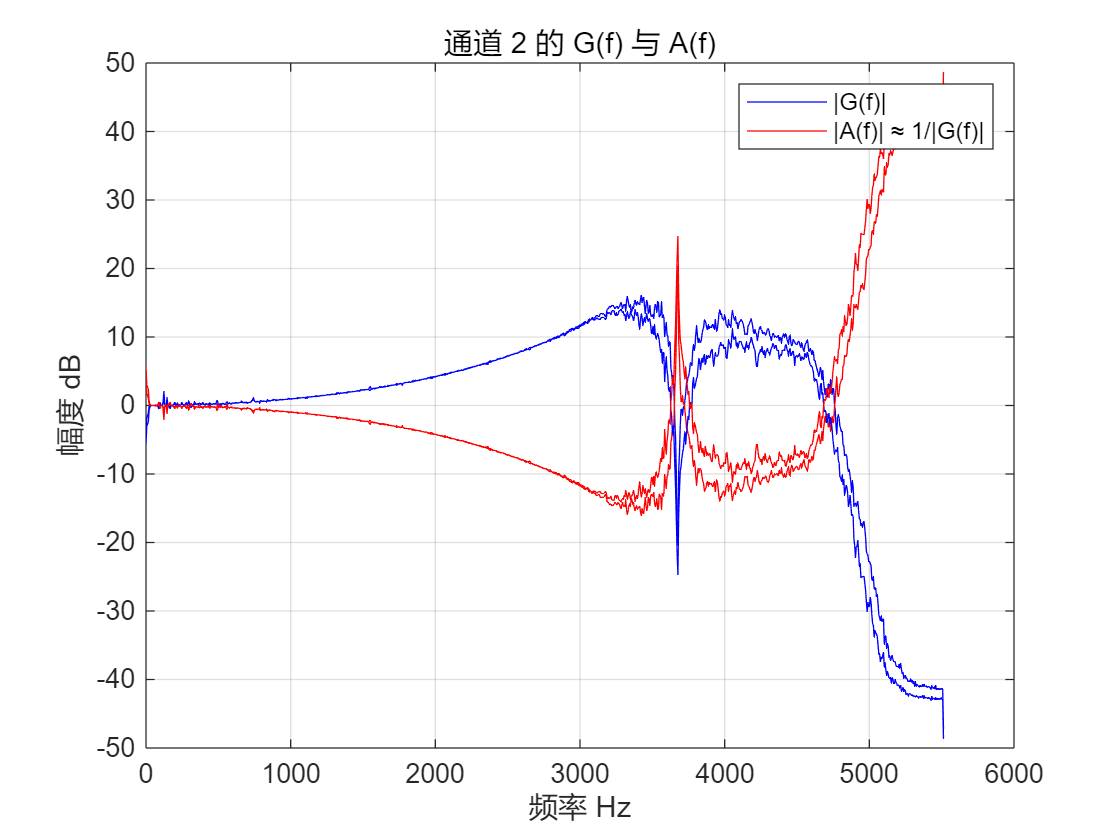

%% 基于频域建模的滤波器反卷积去噪 - 支持全数据长度
clear; clc;
load('Hw2a.mat');  % 包含 Sin_a, Sn_ref_a, fs

% 参数
frame_len = 2048;
overlap = 1024;
win = hamming(frame_len, 'periodic');
M = size(Sin_a,2);
N = size(Sin_a,1);

Sin_est = zeros(N, M);

for ch = 1:M
    x = Sn_ref_a(:,ch);  % 参考输入
    d = Sin_a(:,ch);     % 含噪信号

    % 估计 G(f)
    [Pxy,f] = cpsd(d, x, win, overlap, frame_len, fs);
    [Pxx,~] = pwelch(x, win, overlap, frame_len, fs);
    H_f = Pxy ./ (Pxx + 1e-8);
    A_f = 1 ./ (H_f + 1e-8);  % Inverse filter A(f)

    % 创建对称频谱用于ifft
    H_full = [A_f; conj(flipud(A_f(2:end-1)))];  % 保证ifft是实数
    H_time = real(ifft(H_full));                % 得到时域滤波器
    h_time = H_time(1:frame_len);               % 取前面一帧长度

    % 用这个 FIR 滤波器对 x 做卷积估计噪声
    est_noise = conv(x, h_time, 'same');        % 估计噪声
    e = d - est_noise;                          % 去噪输出
    Sin_est(:,ch) = e;
    
    % 可视化频率响应
    figure(ch);
    plot(f, 20*log10(abs(H_f)+1e-12), 'b'); hold on;
    plot(f, 20*log10(abs(A_f)+1e-12), 'r');
    title(['通道 ', num2str(ch), ' 的 G(f) 与 A(f)']);
    xlabel('频率 Hz'); ylabel('幅度 dB'); grid on;
    legend('|G(f)|','|A(f)| ≈ 1/|G(f)|');
end


%% 播放结果

disp('▶ 基于频域建模的 A(z) 反滤波播放...');

▶ 基于频域建模的 A(z) 反滤波播放...


sound(Sin_est, fs); pause(length(Sin_est)/fs + 1);
